# EL6023 Final Project

Amritpal Singh

Kubilay Ulger

In this project we simulate transmission through a MIMO channel using data from Minsheng's data set. 

## Loading Data and Getting Path Information

Loading Data

clear all %Fresh start
clc 
load roomPathData.mat

Selecting a Rx's with LOS, Getting the path delays, gains and angle of arrivals/departures f

LinkStates = pathData.linkState;
LOS = find(LinkStates==1); %indices for LOS links
NLOS = find(LinkStates==2); %Used later

rxNum = LOS(randi([1,length(LOS)])); %Selecting an RX number from LOS indices

txPos = pathData.txPos; %Getting tx Position

rxPos = pathData.rxPos(rxNum,:); %Getting rx Position

npaths = pathData.npaths(rxNum,:); %Number of paths
gain = pathData.gain(rxNum,:); %Gain of each path
% gain = gain - max(gain); %so that maximum gain is 0dB, makes numbers look nicer
dly = pathData.dly(rxNum,:); %Delay of each path

% Angles 
aoaAz = pathData.aoaAz(rxNum,:)';
aoaEl = pathData.aoaEl(rxNum,:)';
aodAz = pathData.aodAz(rxNum,:)';
aodEl = pathData.aodEl(rxNum,:)';

%We may wish to Rx and Tx towards each other so calculating some parameters
trVec = rxPos' - txPos; %Vector from tx to rx
trVec = trVec/norm(trVec);
zvec = [0,0,1]'; %Antenna elements are directed towards +z by default

tiltAx = cross(zvec,[trVec;0]);
tiltAngle = 90; %Since tiltAx,trVec and zVec are mutually orthogonal


Creating 2 antenna elements, boresights directed to each other

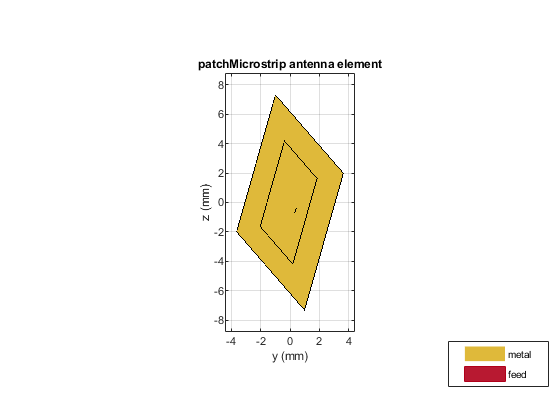

fc = pathData.fc; %Carrier Frequency
elemTx = design(patchMicrostrip, fc); %Simple antenna element
elemTx.Tilt = 90; 
elemTx.TiltAxis = tiltAx';

elemRx = design(patchMicrostrip, fc); %Simple antenna element
elemRx.Tilt = 90; 
elemRx.TiltAxis = -tiltAx';

%Displaying Antennas
elemTx.show()
view(90,0);

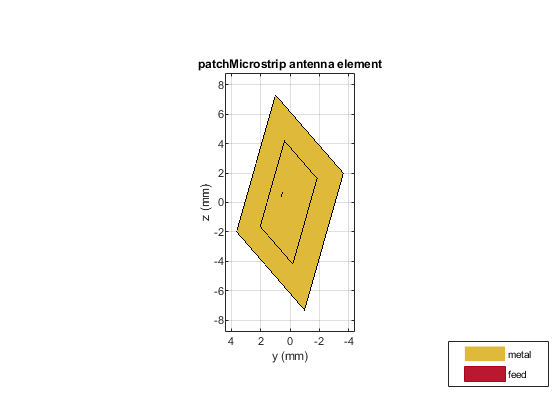

elemRx.show()
view(-90,0);

You can see that antennas are directed at each other.

**Antenna platforms**

%We took these antenna numbers from a demo, they are the usual arrays in
%mmWave
nantgNB = [4,4]; % 16 Antennas at transmitter
nantUE = 8; % 8 Antennas at receiver

lambda = physconst('LightSpeed')/fc; %Wavelength
dstep = lambda/2; %Distance between antennas

arrgNB = phased.URA(nantgNB,dstep,"ArrayNormal","x"); %URA for transmitter
arrUE = phased.ULA(nantUE,dstep,"ArrayAxis","y"); %ULA for receiver

arrPlatformgNB = ArrayPlatform('elem', elemTx, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();

arrPlatformUE =  ArrayPlatform('elem', elemRx, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

Looking at Tx and Rx antennas directivity patterns

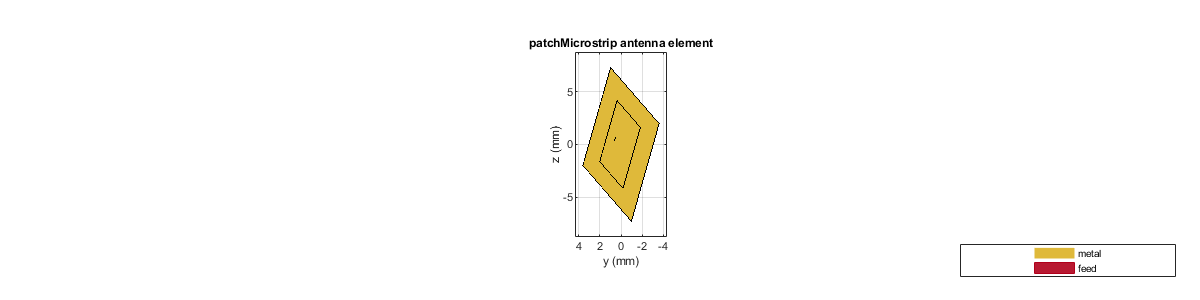

figure(1)
set(gcf,'position',[0,0,1200,300]);

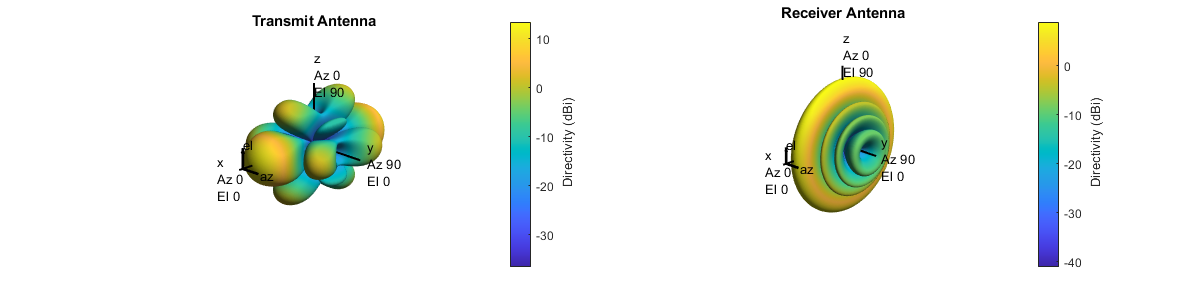

subplot(1,2,1)
arrgNB.pattern(fc);
title('Transmit Antenna')
subplot(1,2,2);
arrUE.pattern(fc);
title('Receiver Antenna')

## **OFDM CHANNEL**

We used the FDMIMOChan class from Lab8 to get chanGrid and the transmitter side average Q=H'*H that will be used in calculating Precoder

SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc);

frameNum = 0;
slotNum = 0;
[chanGrid, Q] = fdchan.step(frameNum, slotNum);

## Transmitter

Now for the transmitter we create a pdfschConfig as usual. So we create a tx object. We kept NumLayers = 1 and generated nstreams of OFDM grids in step function manually

mcsInd = 10;

Modulation = '16QAM';
targetCodeRate = 340/1024;

pdschConfig = nrPDSCHConfig(...
    'Modulation', Modulation, ...
    'PRBSet', (0:NRB-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'PTRS', nrPDSCHPTRSConfig(),...
    'NumLayers', 1);
tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);

So we first we need to pick nstreams such that 1 <= nstreams <= min(Ntx,Nrx) where Ntx and Nrx are transmitter and receiver antenna # respectively

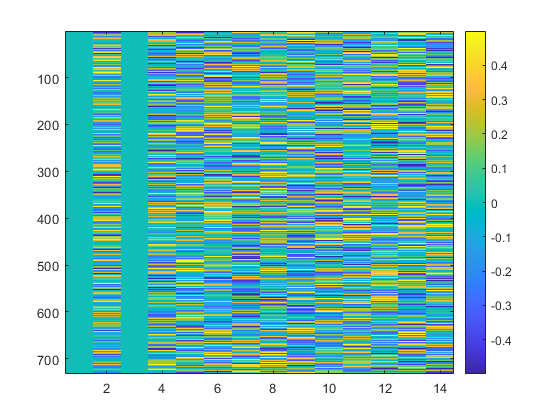

nStreams = 2; %Chosen for dmeonstration

[txGrid,Fprecoder] = tx.step(nStreams,Q);
%The output txGrid is the precoded inside, Tx divides unit power equally
%across nstreams so E||x||^2=1 where x is a vector of size nstreams x 1
figure(2)
imagesc(squeeze(real(txGrid(1,1,:,:))))
colorbar()

## **Channel Operation**

Now we pass precoded grid through the chanGrid and add noise

G = pagemtimes(chanGrid,Fprecoder); %Pre-coded channel, it's assumed that RX knows this.
AvgSNR = 15; %Let's assume this is the SNR we have, we will pick noise variance to match this.
noiseVar = sum(mean(abs(G).^2,[3,4]),'all')/db2pow(AvgSNR)/nantUE/prod(nantgNB);

%Now we pass txGrid through the channel and add noise to obtain received
%grid txGrid
rxGridNoNoise = pagemtimes(chanGrid,txGrid);
rxGrid = rxGridNoNoise + sqrt(noiseVar/2)*(randn(size(rxGridNoNoise))+1j*randn(size(rxGridNoNoise)));

## Receiver

Now we have to perform LMMSE and Decoding to get the received bits! This is all done in UE class. We have modified the UE class from lab 4 to handle LMMSE and multi layer decoding. So we just create an RX object and pass rxGrid, G, noiseVar and nStreams.

rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
rx.step(rxGrid, G, noiseVar,nStreams); %Demodulation

## Testing

%Now we test if we got a throughput
rxBits = rx.rxBits;
txBits = tx.txBits;

CorrectBits = length(find(rxBits == txBits));
TotalBits = length(txBits);


fprintf('%d,%d',CorrectBits,TotalBits)

23056,23056